addpath('./scripts')

Generate synthetic data according to ICA model:

% ica1 = sim_basic_ICA(100, 16, 16, 20000, 5, 1000);
% X = ica1.genX();

Inspect

% seed = 100;
% K = 16;
% V = K;
% M_Tot = 2;
% N = 200000;
% Acond = 5;
% SNR = 999+1/1;
% 
% % iva1 = sim_basic_IVA(seed,K,V,M_Tot,N,Acond,SNR);
% 
% plot(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)','.r')
% h = histogram2(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)','DisplayStyle','tile','Normalization','pdf');
% vals = h.Values;
% x = h.XBinEdges(1:(end-1));
% y = h.YBinEdges(1:(end-1));
% [X,Y] = meshgrid(x,y);
% contour(X',Y',log10(log10(vals+1)))
% corr(iva1.Y{1}(end,:)',iva1.Y{2}(end,:)')
% 
% histogram(iva1.Y{1}(end,:)')
% 

Association between subspaces should be 0:

% plot(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)','.r')
% h = histogram2(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)','DisplayStyle','tile','Normalization','pdf');
% vals = h.Values;
% x = h.XBinEdges(1:(end-1));
% y = h.YBinEdges(1:(end-1));
% [X,Y] = meshgrid(x,y);
% contour(X',Y',log10(log10(vals+1)))
% corr(iva1.Y{1}(1,:)',iva1.Y{2}(end,:)')

Using gsd class directly:

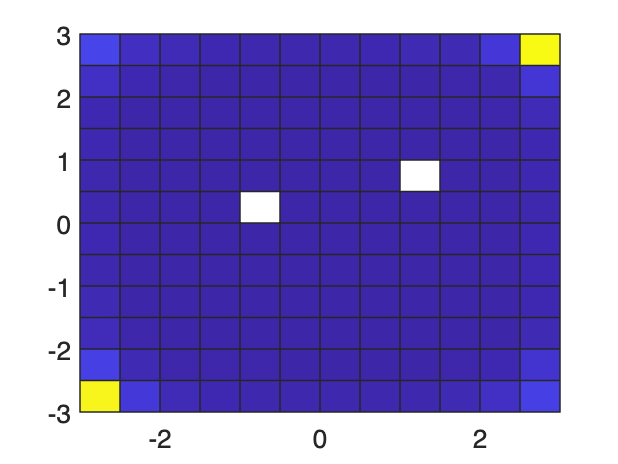

seed = 100;
num_obs = 20000; % 50 500 5000 50000;
total_datasets = 2;
num_subspaces = 16; % 32 64 128

% Subspace Assignment Matrix (SAM)
SAM = num2cell(repmat((1:num_subspaces)', 1, total_datasets));
num_sources = [];
for mm = 1:total_datasets
    num_sources = [num_sources sum([SAM{:,mm}] ~= 0)];
end

% Define parameters for subspace distributions
half_ns = num_subspaces/2;
max_subspace_corr = [linspace(.1,.7,half_ns),linspace(.15,.75,half_ns)]';
subspace_std = 2.^[linspace(2,-3,half_ns),linspace(-3,2,half_ns)]';
nn = 1;
for kk = 1:num_subspaces
    dist_params(kk).name = 'gcp';
    dist_params(kk).mu   = zeros(sum([SAM{kk,:}] ~= 0),1);
    dist_params(kk).CORR = max_subspace_corr(kk);
    if length(dist_params(kk).mu) > 1 && strcmpi(dist_params(kk).name, 'gcp')
        % Define parameters for marginal distributions
        marginal_names = {'laplace', 'logistic', 'normal', 'uniform', 'beta'};%, 'bimodal_gamma'};
        for cc = 1:length(dist_params(kk).mu)
            dist_params(kk).gcp_marginals(cc).name = marginal_names{nn};
            dist_params(kk).gcp_marginals(cc).mu = dist_params(kk).mu(cc);
            switch(lower(dist_params(kk).gcp_marginals(cc).name))
                case 'laplace'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk); % pi/sqrt(3);
                case 'logistic'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                case 'normal'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                case 'uniform'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                case 'beta'
                    dist_params(kk).gcp_marginals(cc).sd = subspace_std(kk);
                    dist_params(kk).gcp_marginals(cc).a = 0.05;
                    dist_params(kk).gcp_marginals(cc).b = 0.05;
                case 'bimodal_gamma'
                    M = .75 * (subspace_std(kk)); % Gamma Mode
                    VV = (.785*subspace_std(kk))^2; % Total Variance (~2*GammaVariance)
                    dist_params(kk).gcp_marginals(cc).a = (VV + 2*M^2 + 2*M*sqrt(VV + M^2))/VV;
                    dist_params(kk).gcp_marginals(cc).b = M/(dist_params(kk).gcp_marginals(cc).a-1);
%                     (a-1)*b
%                     sqrt(a*(b^2))
%                     a
%                     b
                otherwise
                    error('Invalid distribution name.');
            end
            
            
        end
        if nn < length(marginal_names)
            nn = nn + 1;
        else
            nn = 1;
        end
    end
end
data_dim = num_sources;
Atype   = 'Generated';
Acond   = 3;
A       = {};
SNR     = (999+1)/1; % (signal power + noise power) / noise power 
predictors = cell(1, total_datasets);
regtype = 'LS';

sim1    = gsd(seed, num_obs, total_datasets, num_subspaces, num_sources, ...
    SAM, dist_params, data_dim, Atype, Acond, A, SNR, predictors, regtype);

h = histogram2(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)','DisplayStyle','tile','Normalization','pdf');

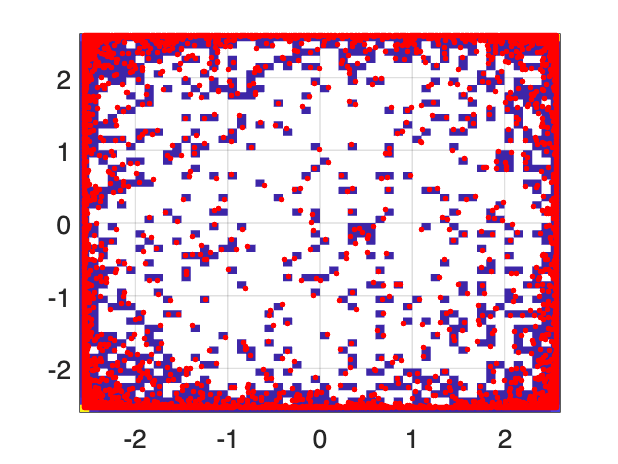

h = histogram2(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)','BinWidth',h.BinWidth./5,'DisplayStyle','tile','Normalization','pdf');
hold on
plot(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)','.r')
hold off

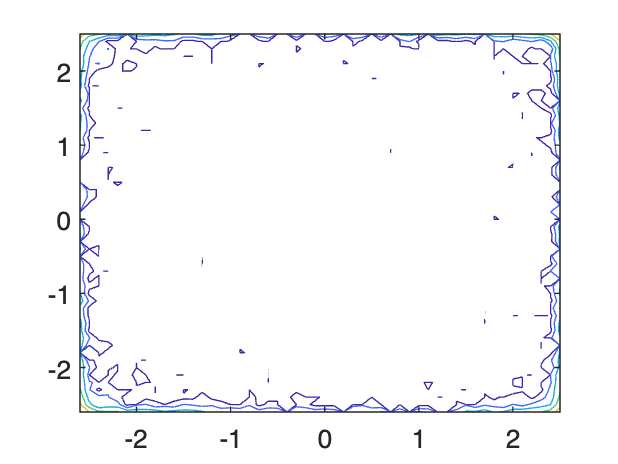


vals = h.Values;
x = h.XBinEdges(1:(end-1));
y = h.YBinEdges(1:(end-1));
[X,Y] = meshgrid(x,y);
contour(X',Y',log10(log10(vals+1)))

corr(sim1.Y{1}(end-1,:)',sim1.Y{2}(end-1,:)')

ans = 0.6369

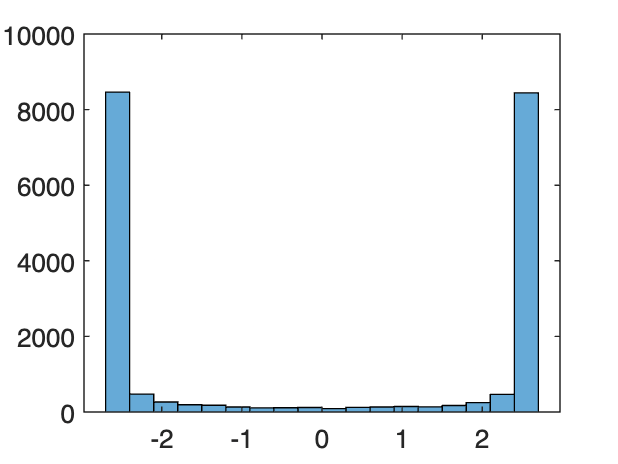


histogram(sim1.Y{1}(end-1,:)')

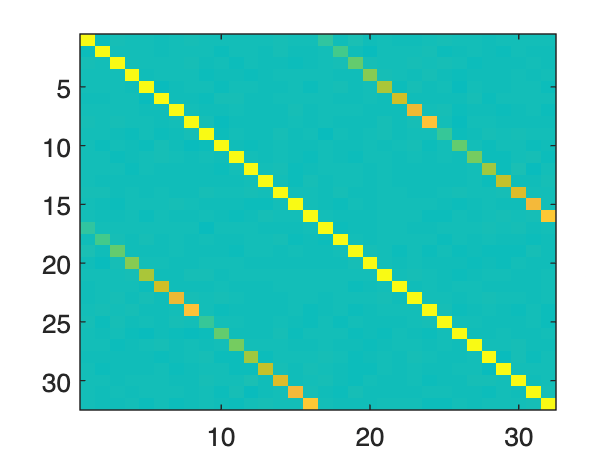


imagesc(corr(cell2mat(sim1.Y')'),[-1 1])

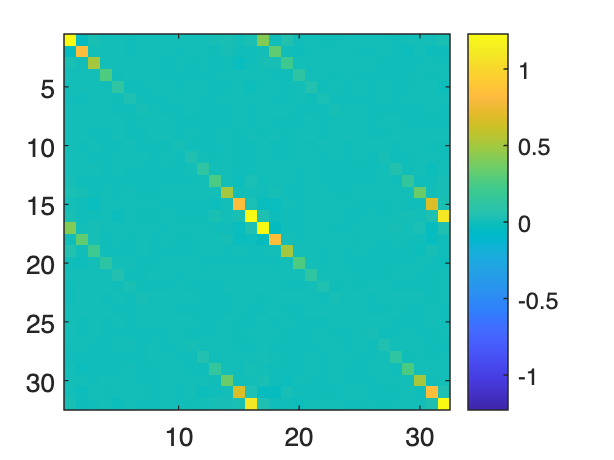

% imagesc(cov(cell2mat(sim1.Y')'),max(max(abs(cov(cell2mat(sim1.Y')'))))*[-1 1])
imagesc(log10(1+cov(cell2mat(sim1.Y')')),max(max(abs(log10(1+cov(cell2mat(sim1.Y')')))))*[-1 1])
colorbar


mean(sim1.Y{1},2)'

ans =    -0.0014    0.0243    0.0016   -0.0028    0.0002    0.0083    0.0204    0.0005   -0.0004    0.0002   -0.0043   -0.0092   -0.0039   -0.0009   -0.0019    0.0088


mean(sim1.Y{2},2)'

ans =     0.0029    0.0184   -0.0145   -0.0004    0.0044   -0.0073    0.0126    0.0011   -0.0001   -0.0027    0.0039   -0.0205   -0.0005   -0.0133   -0.0058    0.0052


std(sim1.Y{1},[],2)'

ans =     3.9768    2.4287    1.4908    0.9054    0.5513    0.3373    0.2055    0.1264    0.1250    0.2051    0.3367    0.5564    0.8993    1.4906    2.4370    3.9279


std(sim1.Y{2},[],2)'

ans =     3.9820    2.4431    1.4735    0.9089    0.5519    0.3412    0.2040    0.1264    0.1246    0.2052    0.3405    0.5542    0.9030    1.4861    2.4345    3.9899


subspace_std'

ans =     4.0000    2.4380    1.4860    0.9057    0.5520    0.3365    0.2051    0.1250    0.1250    0.2051    0.3365    0.5520    0.9057    1.4860    2.4380    4.0000


diag(corr(sim1.Y{1}',sim1.Y{2}'))'

ans =     0.1034    0.1864    0.2710    0.3455    0.4228    0.5189    0.6103    0.7070    0.1370    0.2685    0.3122    0.4003    0.4851    0.5590    0.6369    0.7398


max_subspace_corr'

ans =     0.1000    0.1857    0.2714    0.3571    0.4429    0.5286    0.6143    0.7000    0.1500    0.2357    0.3214    0.4071    0.4929    0.5786    0.6643    0.7500



% Marginal_distribution = laplace, logistic, uniform, bimodal? (group_difference), mismatched (NEW!)

% Num_sources_estiamted = (.5:.25:1.5) * num_sources

Generate mixing matrix A.

Step 1: Use rotation (ortogonal) matrix (R1)

% Rotation (ortogonal) matrix: R1
% This will be used to mix the sources initially
R1 = cell(1, total_datasets);
for dd = 1:total_datasets
    tmp_rnd = randn(data_dim(dd), num_sources(dd));
    [u,s,v] = svds(tmp_rnd, num_sources(dd), 'largest', ...
        'SubspaceDimension', 5*num_sources(dd), 'Tolerance', 1e-14, 'MaxIterations', 1000);
    R1{dd} = u*v';
end

Step 2: Apply rotation and whiten, then update R1

% Sources are mixed using R1:
X = cellfun(@(r,y) r*y, R1, sim1.Y, 'Un', 0);

% % Then whiten X:
% ut = utils;
% wthM_X = cell(1, total_datasets);
% for dd = 1:total_datasets
%     [~, whtM_] = ut.myPCA(X{dd});
%     whtM_X{dd} = whtM_;
% end

% Apply Cholesky decomposition/factorization:
ut = utils;
di_M = cell(1, total_datasets);
for dd = 1:total_datasets
    R = chol(cov(X{dd}'),'lower');
    di_M{dd} = inv(R);
end

% The combined transformation so far:
% R2 = cellfun(@(w,r) w*r, whtM_X, R1, 'Un', 0);
R2 = cellfun(@(d,r) d*r, di_M, R1, 'Un', 0);

Step 3: Apply R2, set variances, and define final orthogonal R2 with expansion to final dimensionality

% Sources are mixed using R2:
% X = cellfun(@(r,y) r*y, R2, sim1.Y, 'Un', 0);

mix_std{1} = diag(2.^[linspace(2,-3,num_subspaces)]')

mix_std = 1×1 cell array
    {16×16 double}

mix_std{2} = diag(2.^[linspace(-2.5,2.5,num_subspaces)]');

% Rotation (ortogonal) matrix: R3
% This will be used to mix the signals further
R3 = cell(1, total_datasets);
for dd = 1:total_datasets
    tmp_rnd = randn(data_dim(dd), num_sources(dd));
    [u,s,v] = svds(tmp_rnd, num_sources(dd), 'largest', ...
        'SubspaceDimension', 5*num_sources(dd), 'Tolerance', 1e-14, 'MaxIterations', 1000);
    R3{dd} = u*v';
end
% The combined transformation so far:
A = cellfun(@(r3,s,r2) r3*s*r2, R3, mix_std, R2, 'Un', 0);
A{1}(1:5,1:5)
A{2}(1:5,1:5)

Final evaluation of mixed signals:

% Sources are mixed using R2:
X = cellfun(@(a,y) a*y, A, sim1.Y, 'Un', 0);

A2 = gen_A_like_CholPCA(X, num_sources);

Unrecognized function or variable 'data_dim'.
Error in gen_A_like_CholPCA (line 23)
    tmp_rnd = randn(data_dim(dd), num_sources(dd));


% The combined transformation so far:
A = cellfun(@(a2,a) a2*a, A2, A, 'Un', 0);
A{1}(1:5,1:5)
A{2}(1:5,1:5)

% Sources are mixed using R2:
X = cellfun(@(a,y) a*y, A, sim1.Y, 'Un', 0);

Try PCA on each dataset:

ut = utils;
whtM_X = cell(1, total_datasets);
for dd = 1:total_datasets
    [~, whtM_] = ut.myPCA(X{dd});
    whtM_X{dd} = whtM_;
end
Xw = cellfun(@(w,x) w*x, whtM_X, X, 'Un', 0);

Mcca = ut.myCCA(Xw,num_sources(1));
Xcca = cellfun(@(m,x) m*x, Mcca, Xw, 'Un', 0);

imagesc(corr(cell2mat(Xcca')'),[-1 1])

Compare to true sources:

imagesc(corr(cell2mat(sim1.Y')',cell2mat(Xcca')'),[-1 1])
ut.MISI(cellfun(@(m,w) m*w, Mcca, whtM_X, 'Un', 0), A, sim1.S)

Try to just standardize the data:

Xs = X;
for dd = 1:total_datasets
    Xs{dd} = X{dd}./repmat(std(X{dd},[],2),1,size(X{dd},2));
end

Mcca = ut.myCCA(Xs,num_sources(1));
Xcca = cellfun(@(m,x) m*x, Mcca, Xs, 'Un', 0);

imagesc(corr(cell2mat(Xcca')'),[-1 1])

Matlab's CCA:

[A,B,r,U,V] = canoncorr(Xs{1}',Xs{2}'); % REVIEW!! Somehow A, B are Not orthogonal??
imagesc(corr([U,V]),[-1 1])


Try a Tall mixing matrix A: orthogonal vs non-orthogonal

Goal: try 4 levels of num_samples, noise?, NIPALS, mis-specify num_sources (.5x, 1.5x)